# EE525 - Project 3

Author: Grant Gallagher

## Initialization

clc;
clear;

## 1. FIR and IIR Filters

Consider a white Gaussian discrete-time random process X[n] with amplitude of 1 as input to the following filter

$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack$ (1)

### 1.1 Analytical Solution

 Simulate the random process $X\left\lbrack n\right\rbrack$ by a series of $N=50000$ samples that are i.i.d. and generated from Gaussian random variables with zero mean and unit variance.  Verify that the simulated sequence is white noise analytically and experimentally.

N = 50000;
x = randn([N 1]);
figure;
Rx = autocorrelation(x)

Rx =     1.0000
    0.0064
   -0.0012
    0.0028
   -0.0000
   -0.0031
   -0.0018
    0.0018
    0.0024
   -0.0104


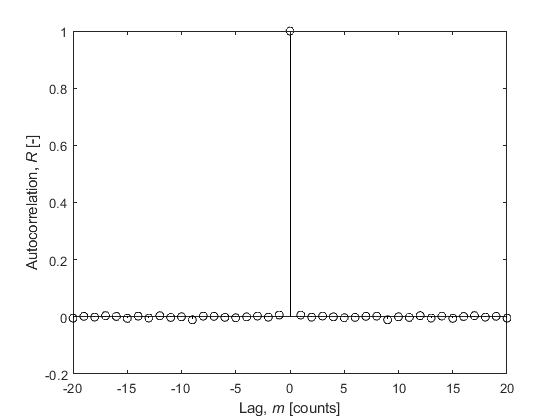

plotR(Rx)

### 1.2 Subplots

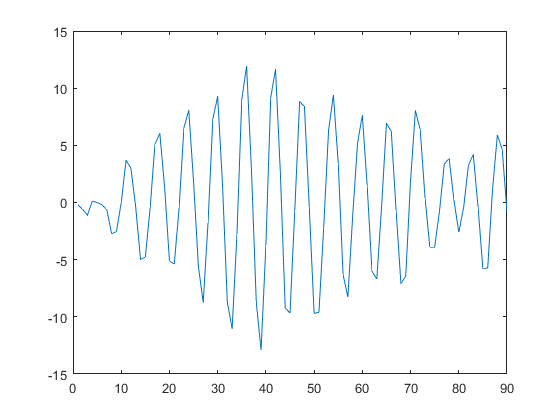

a = [1];
b = [1 -1 1];
y = filter(a, b, x);
plot(y(1:90))

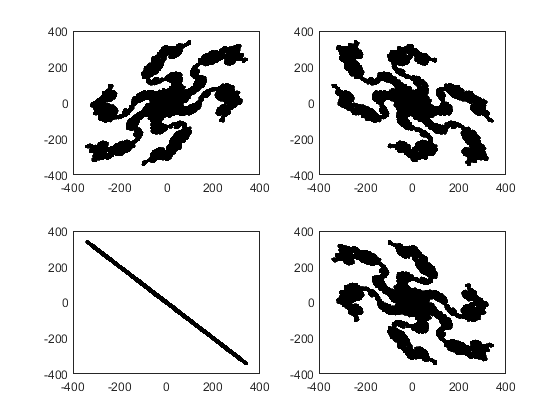

figure;
subplot(2,2,1);
plot(y(1:end-1), y(2:end),'.','Color',[0 0 0])
subplot(2,2,2);
plot(y(1:end-2), y(3:end),'.','Color',[0 0 0])
subplot(2,2,3);
plot(y(1:end-3), y(4:end),'.','Color',[0 0 0])
subplot(2,2,4);
plot(y(1:end-4), y(5:end),'.','Color',[0 0 0])

### 1.3 Autocorrelation

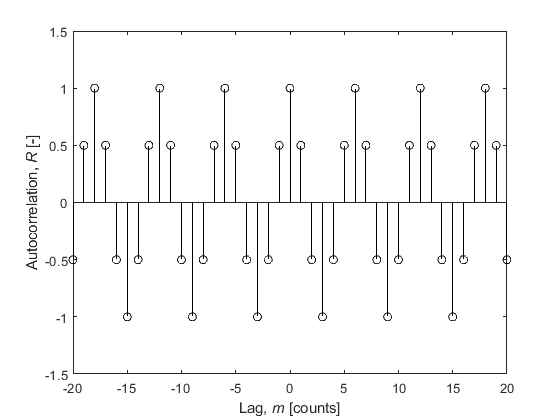

Ry = autocorrelation(y);
figure;
plotR(Ry)

### 1.4 Power Spectral Density Function

x = [1:0.01:10000]

x = 	1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


y = 20*sin(2*pi*x) + randn(1,length(x))

y =     0.3023    1.8649    3.0666    3.9603    4.1356    6.0251    7.1770    8.3798    9.4709   10.1458   13.5656   14.3401   14.1535   15.5064   16.6002   16.2467   17.0112   18.0812   18.6021   18.3531   20.1693   17.9609   19.2052   19.2177   19.5567   19.6815   18.0889   18.2569   19.4660   19.9802   19.0808   18.0081   15.2819   17.4905   16.7089   16.4275   15.5268   15.0655   14.0412   13.2832   10.7823   11.1155   10.0419    9.3933    8.6769    6.6499    5.9106    2.7187    3.8427    1.5216


N = length(x)

N = 999901






Fy = (abs(fft(y)).^2)./N;
P2 = abs(Fy/N);
P1 = P2(1:N/2+1);

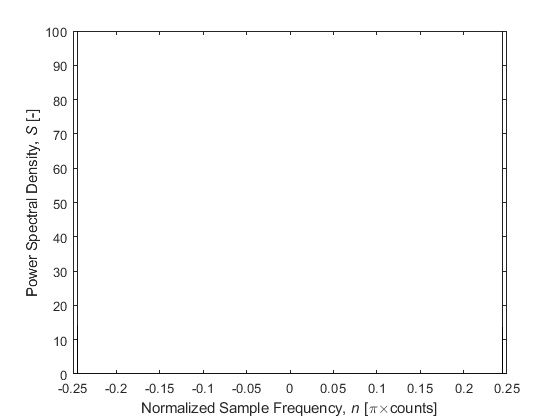

P1(2:end-1) = 2*P1(2:end-1);
f = (-N/2:N/2-1)/(2*N);
plot(f,P2,'Color','Black') 
xlabel('Normalized Sample Frequency, {\itn} [\pi\timescounts]')
ylabel('Power Spectral Density, {\itS} [-]')

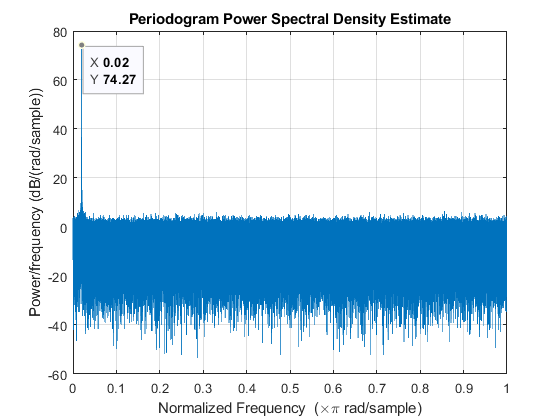


periodogram(y)

- Filter $X\left\lbrack n\right\rbrack$ using (1).  Note you can use filter() in MATLAB to generate the output sequence $Y\left\lbrack n\right\rbrack$.

- Plot the probability density function of Y[i], i=1,2,..., N. Explain the results.

- Draw 4 scatter plots using subplot(22n), n=1,2,3,4. The first scatter plot should consist of points (Y[i], Y [i +1]). This correlates samples that are separated by a lag of “1”. The other 3 scatter plots should consist of points (Y[i], Y [i +2]), (Y[i], Y [i+3]), (Y[i], Y [i +4]), I = 1, 2, ..., N-10, respectively. What can you conclude about the output random process from all the plots?

- Evaluate the autocorrelation function RY[m] from the sample autocorrelation of Y[n]. Plot both the theoretical autocorrelation and the sample autocorrelation versus 𝑚𝑚 for  −20≤𝑚𝑚≤20. Note it is necessary to take the ensemble average of the function of interest.  Explain any discrepancies.

- Evaluate the power spectral density function of Y[n]   by (a) periodogram (don’t use the built-in function), and (b) DTFT of the autocorrelation function. Note these may be evaluated using fft() from MATLAB. To get reasonable results, it is necessary to take the ensemble average of the functions of interest. Again compare these with the theoretical results and explain any discrepancies.

- Is there any relationship between the input and output PSDs? Why or why not?

- Repeat steps 2-5 with the following system

$y\left\lbrack n\right\rbrack -0\ldotp 95y\left\lbrack n-1\right\rbrack =x\left\lbrack n\right\rbrack$ (2)

## Mean Function

function mu = average(S)
    mu = sum(S)/length(S);
end

### Variance Function

function sigma_2 = variance(S)
    sigma_2 = sum((S-average(S)).^2)/(length(S)-1);
end

### Autocorrelation Function

function R = autocorrelation(sample, size)
    N = length(sample);
    R = zeros(length(N), 1);
    sample_avg = average(sample);
    for n = 0:20
        sum1 = 0;
        sum2 = 0;
        for k = 1:(N-n)
            sum1 = sum1 + (sample(k)-sample_avg)*(sample(k+n)-sample_avg);
            sum2 = sum2 + (sample(k)-sample_avg)^2;
        end
        R(n+1) = sum1/sum2;
    end
    R = R';  
end

### Plot Autocorrelation

function plotR(R)
    R_positive = R(2:end);
    R_negative = flip(R_positive);
    
    Ry_plot = [R_negative; R(1); R_positive];
    indices = linspace(-(length(R)-1),(length(R)-1),length(R)*2-1);
    
    stem(indices, Ry_plot,'Color',[0 0 0])
    xlabel('Lag, {\itm} [counts]')
    ylabel('Autocorrelation, {\itR} [-]')
end